clc
clear all
g=9.81;
R=g/9;
thetad0=0;
theta0=1;
gamma=0.5;
[t,w]=pendulum3(R,theta0,thetad0,gamma);
ind1= find(w(:,2).*circshift(w(:,2), [-1 0]) <= 0);
period1= 2*mean(diff(t(ind1(1:length(ind1)-1))));
omega1=2*pi/period1

omega1 = 2.9710

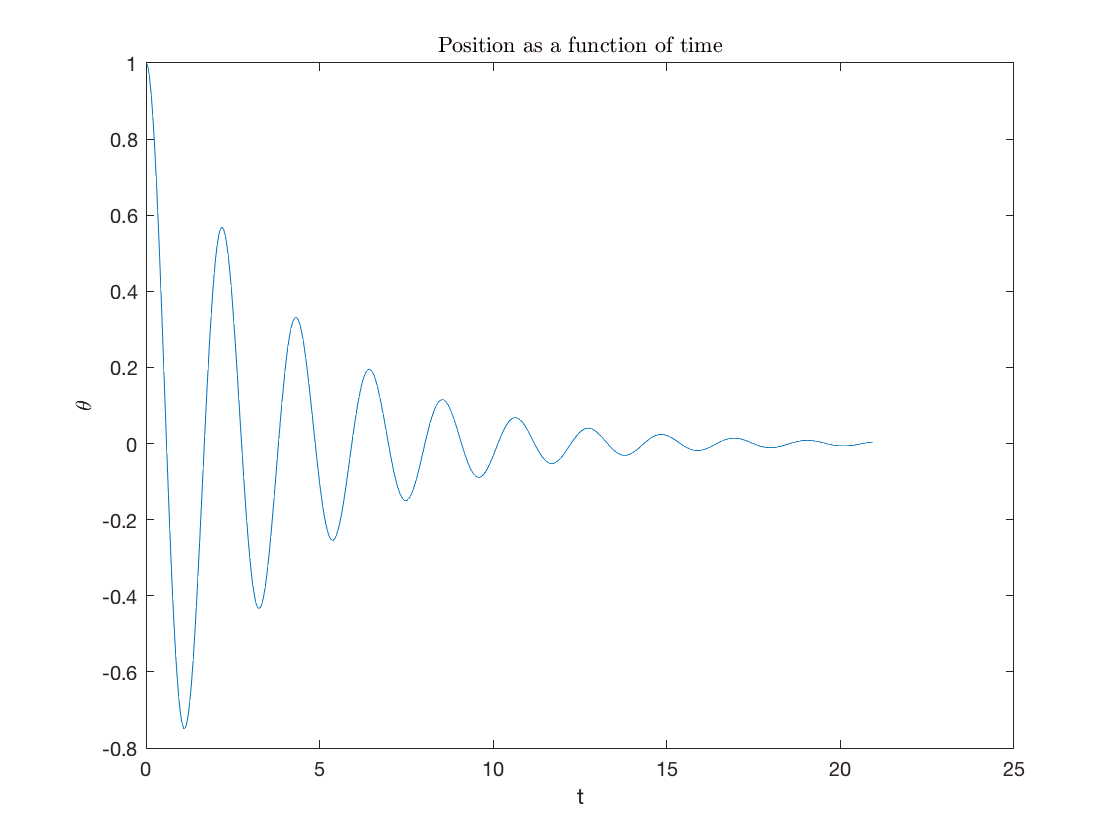

plot(t,w(:,1))
xlabel('t')
ylabel('\theta')
title('Position as a function of time','interpreter','latex')

(a) Damped oscillations

[t1,w1]=pendulum(R,theta0,thetad0);
ind2= find(w1(:,2).*circshift(w1(:,2), [-1 0]) <= 0);
period2= 2*mean(diff(t1(ind2(1:length(ind2)-1))));
omega2=2*pi/period2

omega2 = 2.8182

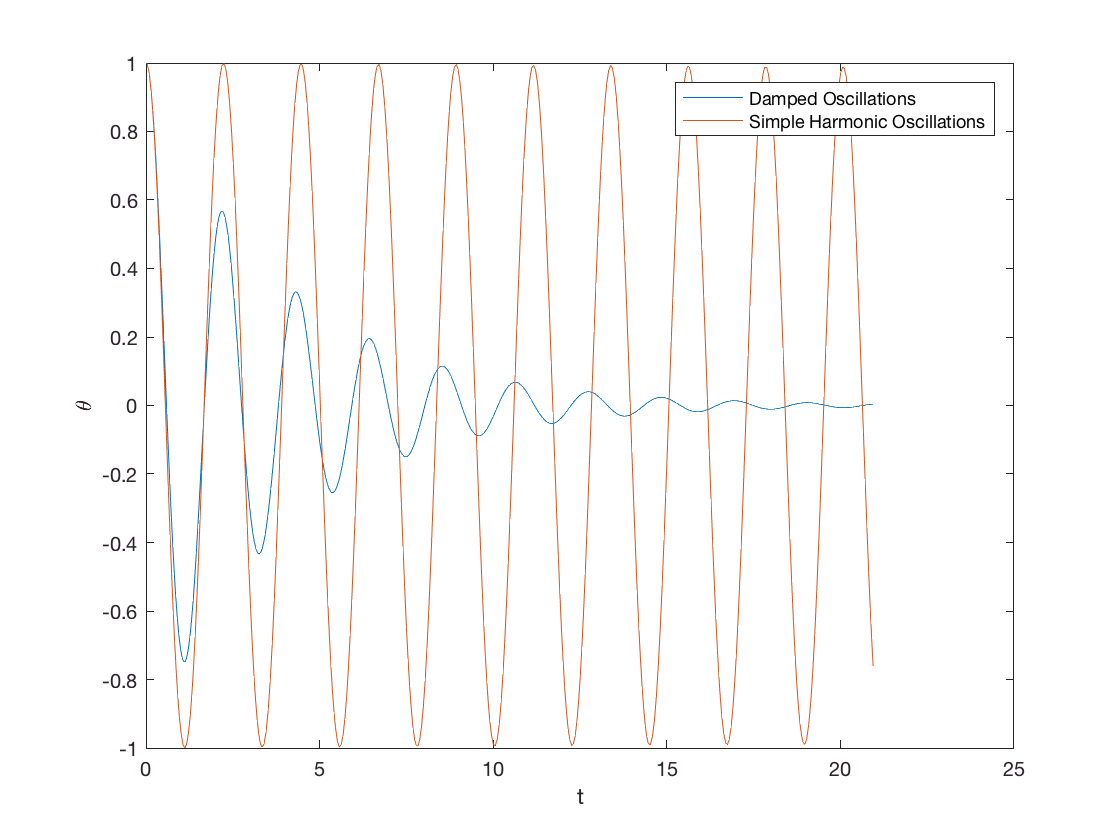

plot(t,w(:,1),t1,w1(:,1))
xlabel('t')
ylabel('\theta')
legend('Damped Oscillations','Simple Harmonic Oscillations')

(b) T_damped = 2.1148 s; T_undamped = 2.2295s; omega_damped = 2.9710 rad/s; omega_undamped = 2.88182 rad/s

Period will be shorter in damped oscillations.  

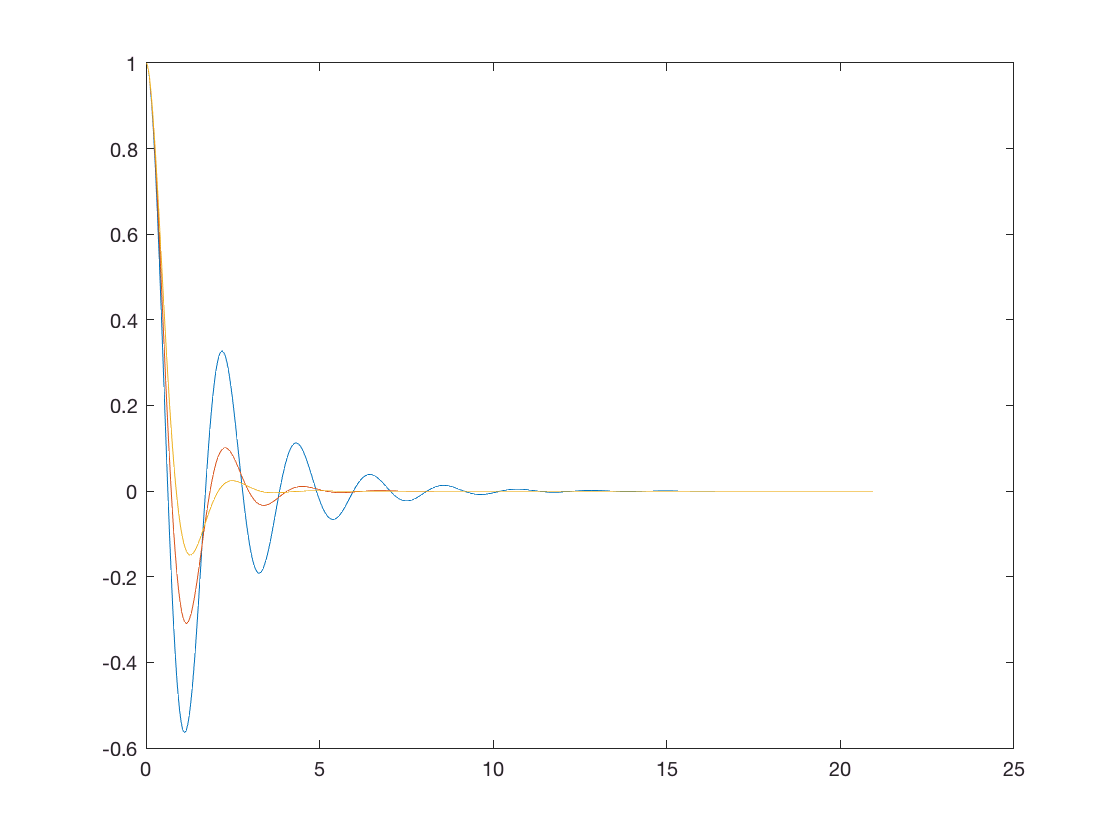

for gamma=1:3
    [t,w]=pendulum3(R,theta0,thetad0,gamma);
    ind= find(w(:,2).*circshift(w(:,2), [-1 0]) <= 0);
    period= 2*mean(diff(t(ind(1:length(ind)-1))));
    omega(gamma)=2*pi/period;
    plot(t,w(:,1))
    hold on
end
hold off

ind=zeros;

(b) omega1 = 2.9536; omega2 = 3.1118; omega3 = 3.2881; the frequency increase with greater damping.

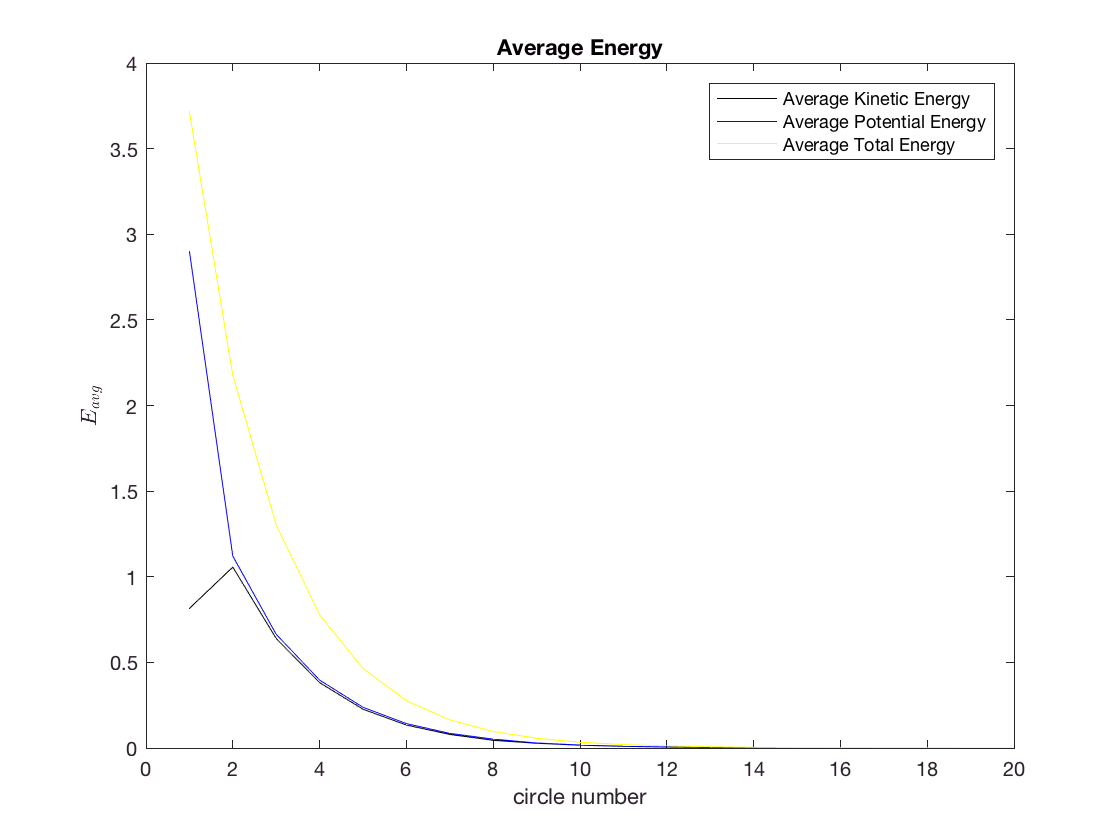

gamma=0.5;
[t,w]=pendulum3(R,theta0,thetad0,gamma);
K=0.5*R^2*w(:,2).^2;
V=0.5*9*R^2*(sin(w(:,1))).^2;
ind= find(w(:,2).*circshift(w(:,2), [-1 0]) <= 0);
for i=1:length(ind)-1
    for j=1:ind(i+1)-ind(i)
        K1(j)=K(ind(i)+j-1);
        V1(j)=V(ind(i)+j-1);
    end
    avgK(i)=mean(K1);
    avgV(i)=mean(V1);
    avgE(i)=avgK(i)+avgV(i);
    K1=zeros;
    V1=zeros;
    circle(i)=i;
end
plot(circle,avgK,'k-',circle,avgV,'b-',circle,avgE,'y-')
legend('Average Kinetic Energy','Average Potential Energy','Average Total Energy')
xlabel('circle number')
ylabel('$E_{avg}$','interpreter','latex')
title('Average Energy')

(c) The decrease is not uniform 

gamma = 4

gamma = 5

gamma = 6

gamma = 7

gamma = 8

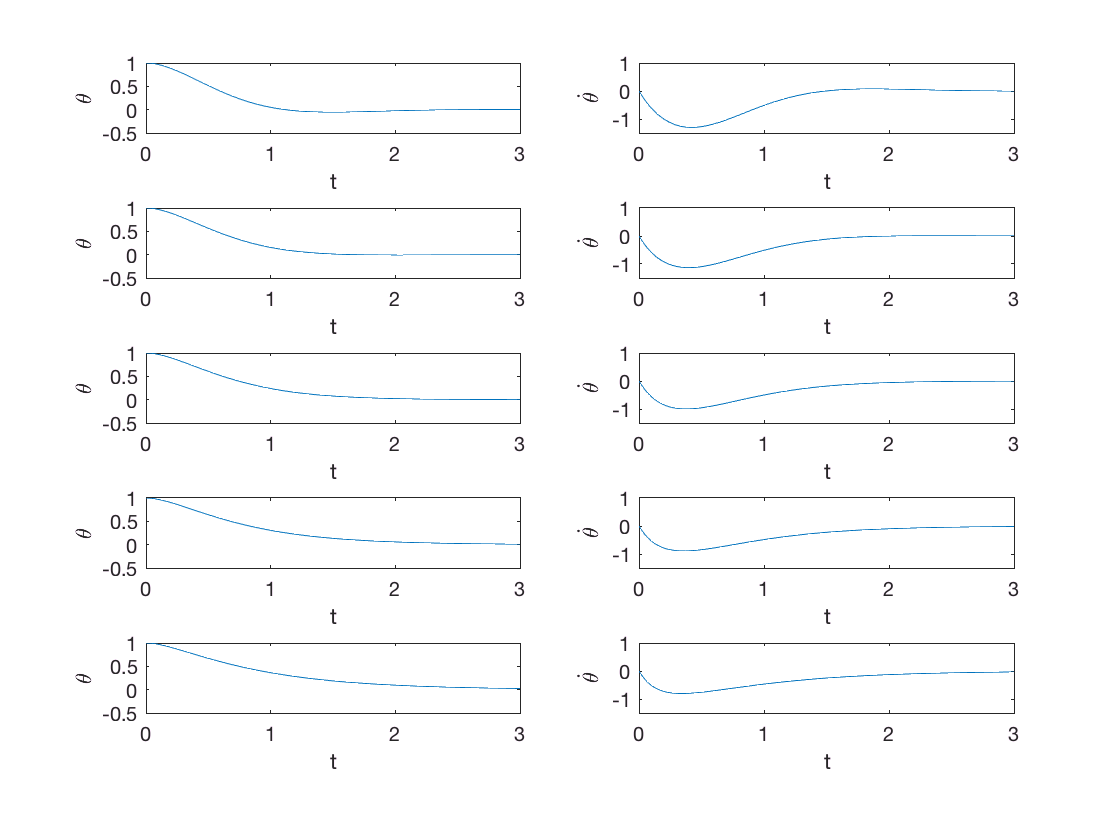

clc
for gamma=4:8
    [t,w]=pendulum3(R,theta0,thetad0,gamma);
    subplot(5,2,2*gamma-7)
    plot(t,w(:,1))
    xlabel('t')
    ylabel('\theta')
    axis([0,3,-0.5,1])
    subplot(5,2,2*gamma-6)
    plot(t,w(:,2))
    xlabel('t')
    ylabel('$\dot{\theta}$','interpreter','latex')
    axis([0,3,-1.5,1])
end